# **PESTools - Example 010-012 - ARPES Eb(kx) Data Processing**

## PCC

This example shows how to perform common operations on ARPES data using the functions of the MATools and PESTools toolkit.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

% Code initialisation
close all; clear all;
pp          = plot_props();
data_path   = 'G:\My Drive\GitHub\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\';

# **ARPES Eb(kx) Data Processing**

**(A) Loading in the ARPES data files**

% Loading in the data files
file_names      = {...
    '010_ARPES_HSCUT.h5',...
    };
arpes_dat = cell(1,length(file_names));
for i = 1:length(file_names); arpes_dat{i} = load_adress_data(file_names{i}, data_path); end

Loading ARPES data...


- Data slice formation
- Re-mapping


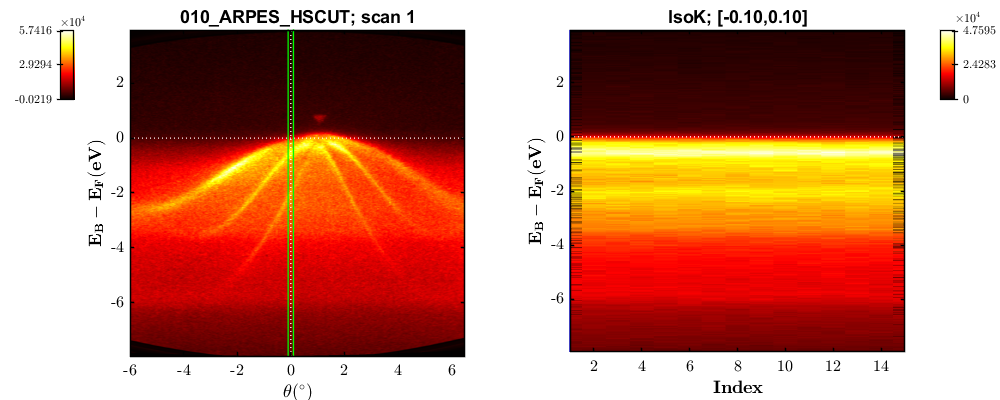

view_data(arpes_dat{1});

% Cross-correlating the data files
for i = 1:length(arpes_dat); arpes_dat{i} = xcorr_scans(arpes_dat{i}); end

- Correlating scans
Scan = 2: Offset = 0.01728
Scan = 3: Offset = 0.01728
Scan = 4: Offset = 0.01728
Scan = 5: Offset = 0.02592
Scan = 6: Offset = 0.02592
Scan = 7: Offset = 0.02592
Scan = 8: Offset = 0.02592
Scan = 9: Offset = 0.02592
Scan = 10: Offset = 0.02592
Scan = 11: Offset = 0.03456
Scan = 12: Offset = 0.03456
Scan = 13: Offset = 0.03456
Scan = 14: Offset = 0.03456
Scan = 15: Offset = 0.03456


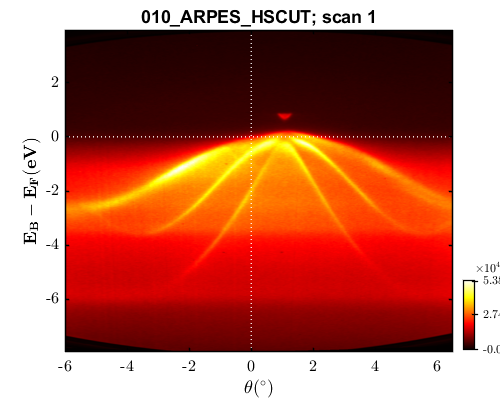

view_data(arpes_dat{1});

**(B) Loading in the Fermi-Edge reference files**

% Loading in the data files
file_names_ef      = {...
    '010_ARPES_HSCUT_EF.h5',...
    };
arpes_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); arpes_ref{i} = load_adress_data(file_names_ef{i}, data_path); end

Loading ARPES data...


- Data slice formation
- Re-mapping


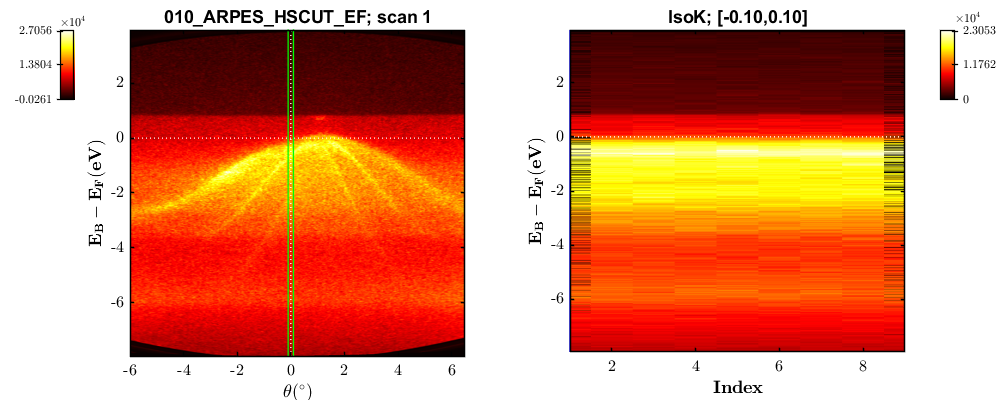

view_data(arpes_ref{1});

% Cross-correlating the reference files to get a good estimate on EF
for i = 1:length(arpes_ref); arpes_ref{i} = xcorr_scans(arpes_ref{i}); end

- Correlating scans
Scan = 2: Offset = 0
Scan = 3: Offset = 0
Scan = 4: Offset = 0
Scan = 5: Offset = 0
Scan = 6: Offset = 0
Scan = 7: Offset = 0
Scan = 8: Offset = 0
Scan = 9: Offset = 0


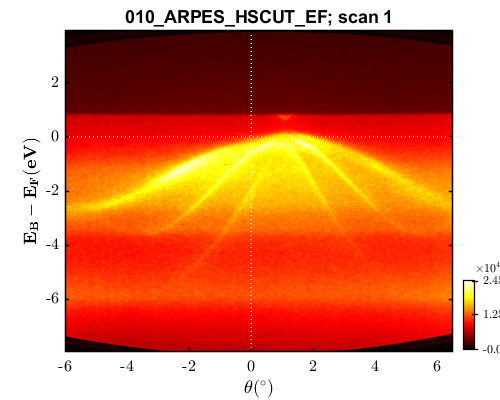

view_data(arpes_ref{1});

**(C) Binding energy alignment to the reference data**

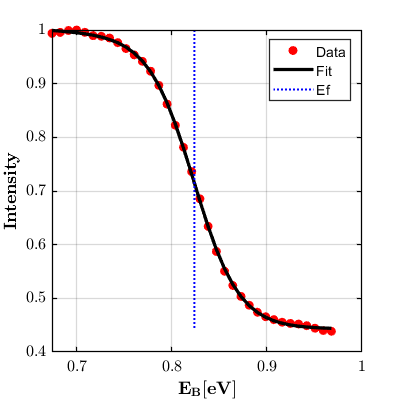

alignType   = "fit2ref";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.82;             % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 0.15;             % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat}; 
for i = 1:length(arpes_dat)
    arpes_dat{i}  = align_energy(arpes_dat{i}, align_args, arpes_ref{1}, 1); 
end

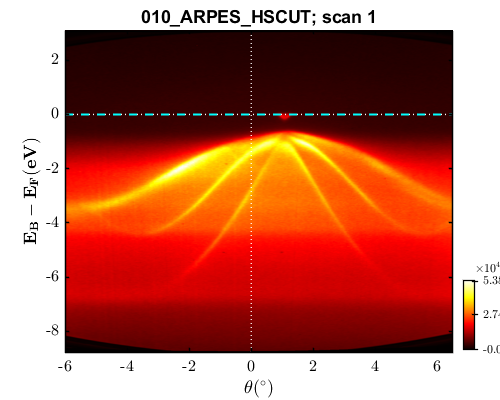

view_data(arpes_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(D) Background subtraction and intensity normalisation**

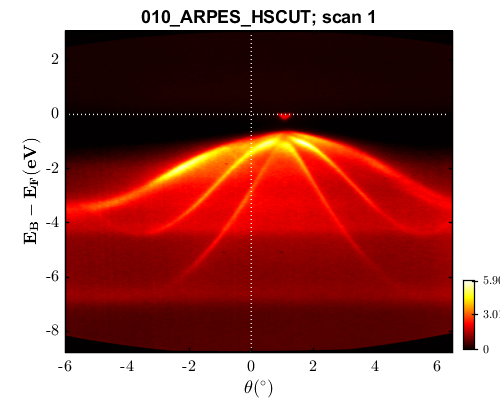

bgrdType    = "angle/kx-int (fixed edc) (per channel)";   % either "angle/kx-int (fixed edc)", "angle/kx-int (fixed edc) (per channel)", "angle/kx-int (fixed mean)", "angle/kx-int (moving mean)", "none"
bgrdWin     = [-5, 5];                  % EDC angle range to integrate over to extract ISubtr
bgrdScale   = 0.50;                         % scale coefficient to subtract (Data - intScale * ISubtr)
bgrdSmooth  = 100;                          % single, constant value that determine presmoothing of data to extract background. 
normType    = "mean (each scan)";           % "max (all scans)", "max (each scan)", "mean (each scan)", "none"
bgrd_args   = {bgrdType, bgrdWin, bgrdScale, bgrdSmooth, normType}; 
for i = 1:length(arpes_dat)
    arpes_dat{i} = bgrd_subtr_data(arpes_dat{i}, bgrd_args); 
end
view_data(arpes_dat{1});

**(E) Wave-vector conversions**

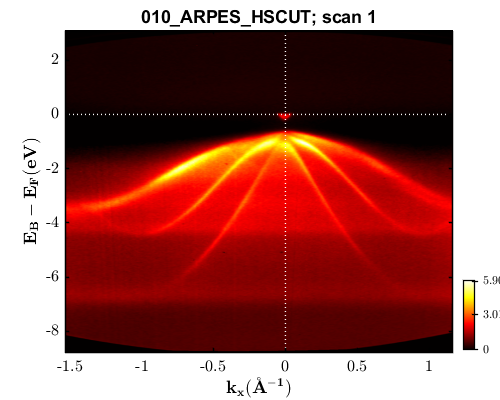

eB_ref      = 0;            % single, constant value of the binding energy at the refernece point.
kx_ref      = 0;            % single, constant value of the wave-vector value at the reference point.
thtA_ref    = 1.10;         % single, constant value of the tht angle value at the reference point.
v000        = 12.57;        % single, constant value of the inner potential. Tune to make sure spacing of Gamma points is correct. Default is 12.57.
kconv_args  = {eB_ref, kx_ref, thtA_ref, v000}; 
for i = 1:length(arpes_dat)
    arpes_dat{i} = convert_to_k(arpes_dat{i}, kconv_args);
    % -- custom shift to centralise kx
    arpes_dat{i}.kx = arpes_dat{i}.kx;
end
view_data(arpes_dat{1});

**(F) Cropping the ARPES data**

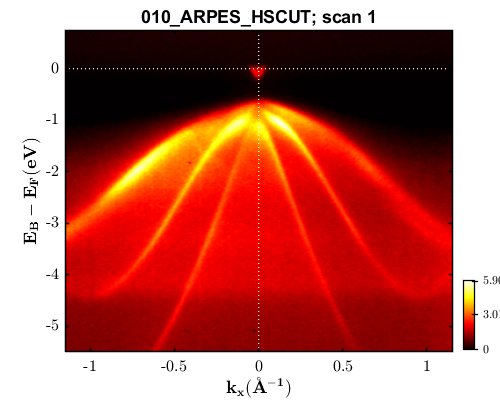

ans = struct with fields:
       FileName: '010_ARPES_HSCUT'
         H5file: '010_ARPES_HSCUT.h5'
           Type: "Eb(k)"
          index: 1
           meta: [1×1 struct]
       raw_data: [1376×391 double]
        raw_tht: [1×391 double]
         raw_eb: [1376×1 double]
            deb: 0.0450
             hv: 586
            dhv: 0.0750
           tltM: 2.8006
           thtM: 0
           Temp: 81.9000
      eb_shifts: {[0.8238]}
    eb_ref_file: '010_ARPES_HSCUT_EF'
             eb: [724×335 double]
            tht: [724×335 double]
           data: [724×335 double]
      surfNormX: 0.1924
             kx: [724×335 double]
             ky: 0.6060
             kz: 12.5700


xLims       = [-1.15, 1.15];    % x-axis limits to crop (if empty like [], does not crop this axis)
yLims       = [-5.5, 0.75];     % y-axis limits to crop (if empty like [], does not crop this axis)
zLims       = [];               % z-axis limits to crop (if empty like [], does not crop this axis)
for i = 1:length(arpes_dat) 
    arpes_dat{i} = data_crop3D(arpes_dat{i}, xLims, yLims, zLims);
    view_data(arpes_dat{i}); arpes_dat{i}
end

# **APPENDIX : A LIST OF USEFUL FUNCTIONS**

## Appendix I - Extracting *iso-cut* profiles

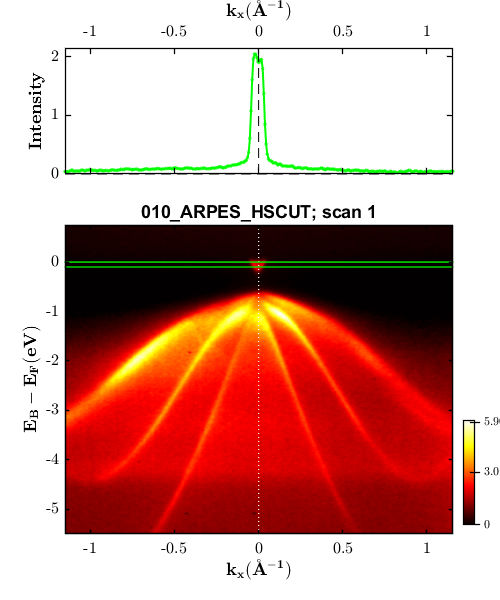

cutStr_01 = struct with fields:
    isocut_args: {[1]  ["MDC"]  [-0.1000 0]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "MDC"
         IsoVal: -0.0500
         IsoWin: 0.0500
         IsoNum: 1
           XCut: [1×335 double]
           DCut: [1×335 double]


nFrame          = 1;                    % Scan number to be cut
% -- EXTRACT MDC CUT
cutType         = "MDC";                % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = [-0.1, 0.0];          % Integration window of the cut to be made.
isocut_args     = {nFrame, cutType, cutWin};
[cutStr_01, ~]  = extract_isoCut(arpes_dat{1}, isocut_args); cutStr_01

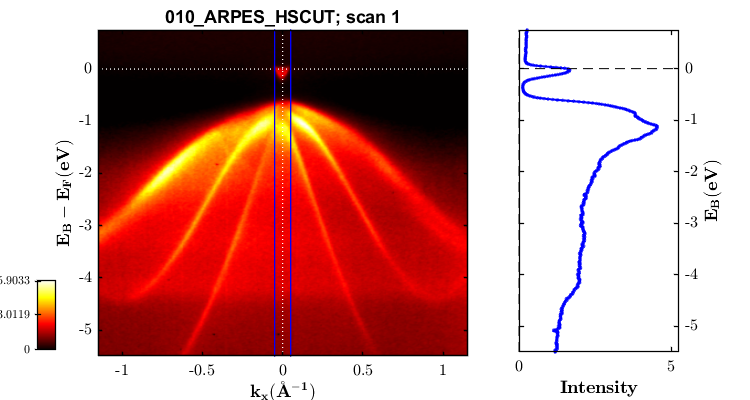

cutStr_02 = struct with fields:
    isocut_args: {[1]  ["EDC"]  [-0.0500 0.0500]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "EDC"
         IsoVal: 0
         IsoWin: 0.0500
         IsoNum: 1
           XCut: [724×1 double]
           DCut: [724×1 double]


% -- EXTRACT EDC CUT
cutType         = "EDC";                % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = [-0.05, 0.05];        % Integration window of the cut to be made.
isocut_args     = {nFrame, cutType, cutWin};
[cutStr_02, ~]   = extract_isoCut(arpes_dat{1}, isocut_args); cutStr_02

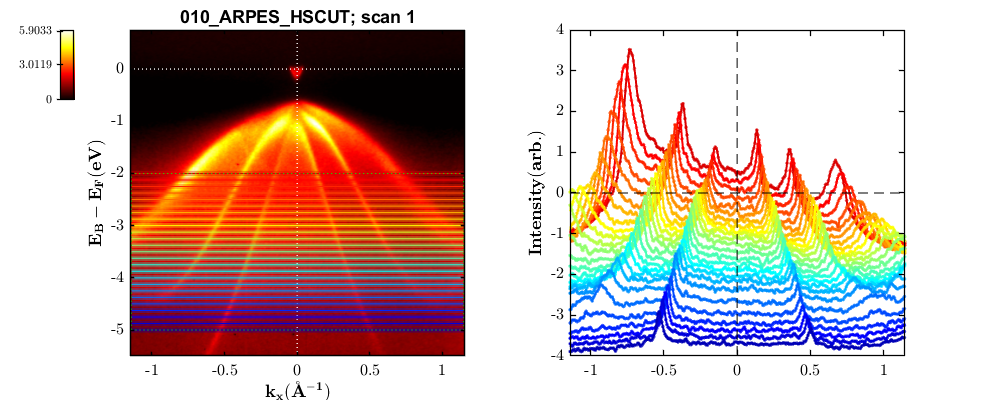

cutStr_03 = struct with fields:
    isocut_args: {[1]  ["MDC"]  [0.0500]  [-1.7500 1.7500]  [-5 -2]  [25]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "MDC"
         IsoVal: [-5 -4.8750 -4.7500 -4.6250 -4.5000 -4.3750 -4.2500 -4.1250 -4 -3.8750 -3.7500 -3.6250 -3.5000 -3.3750 -3.2500 -3.1250 -3 -2.8750 -2.7500 -2.6250 -2.5000 -2.3750 -2.2500 -2.1250 -2]
         IsoWin: [-0.0500 0.0500]
         IsoNum: 25
           XCut: {1×25 cell}
           DCut: {1×25 cell}


% -- EXTRACT SERIES OF MDC CUTS
isocutType          = "MDC";            % Type of line profile to extract. "EDC" (vertical) or "MDC" (horizontal)
isocutWin           = 0.05;             % single, constant valueof the integration window.
isocutXLims         = [-1.75, 1.75];    % 1x2 vector which gives the x-axis limits of the train [minX, maxX]
isocutYLims         = [-5, -2];         % 1x2 vector which gives the y-axis limits of the train [minY, maxY]
isocutN             = 25;               % single, constant value that determines the total number of line profiles to extract
isocut_args         = {nFrame, isocutType, isocutWin, isocutXLims, isocutYLims, isocutN};
plot_result         = 1;                % Show a plot of the data that is extracted. if 1, it will make the plot, if 0 it won't.
[cutStr_03, ~]      = extract_isoCut_series(arpes_dat{1}, isocut_args, plot_result); cutStr_03

## Appendix II - Finding the VBM position using the leading edge method

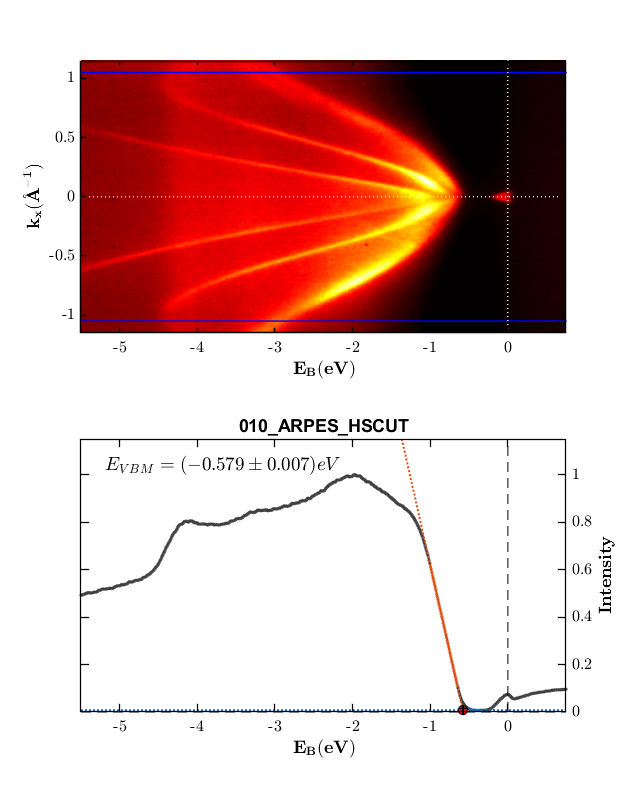

ans = struct with fields:
    vb_fit_args: {[-1.0500 1.0500]  [-0.4800 -0.3280]  [-1 -0.6500]  []}
           XCut: [724×1 double]
           DCut: [724×1 double]
      XCut_back: [18×1 double]
      DCut_back: [18×1 double]
      XCut_edge: [41×1 double]
      DCut_edge: [41×1 double]
       fit_back: [1×1 struct]
       fit_edge: [1×1 cfit]
             XX: [1000×1 double]
        DD_back: [1000×1 double]
        DD_edge: [1000×1 double]
            VBM: -0.5790
           dVBM: 0.0070
        VBM_int: 0.0080
       dVBM_int: 0.0060


VB_LE_fit       = {};
bgrnd_type      = "poly0";                  % "poly0" (flat background), "poly1" (linear background), "none" (to the x-axis baseline)
kWin_edc        = 0.00 + [-1.05, 1.05];     % window of the EDC taken around the VBM position
eWin_back	    = [-0.48, -0.328];          % window of the background region within the EDC cut
eWin_edge	    = [-1.00, -0.65];           % window of the VBM leading edge region within the EDC cut
dESmooth        = [];                       % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
iparams         = {kWin_edc, eWin_back, eWin_edge, dESmooth}; 
for i = 1:length(arpes_dat)
    % -- Finding the VBM position from the leading edge fit
    VB_LE_fit{i} = vb2le_solver(arpes_dat{i}.kx, arpes_dat{i}.eb, arpes_dat{i}.data, bgrnd_type, iparams, 1);
    title(arpes_dat{i}.FileName, 'Interpreter','none');
    % -- Print the final fit
    VB_LE_fit{i}
end

% -- Finding the best estimate of the VBM and BOFF based on multiple data files
VBM = []; dVBM = [];
for i = 1:length(arpes_dat)
    VBM(i)      = VB_LE_fit{i}.VBM;
    dVBM(i)     = VB_LE_fit{i}.dVBM;
end
VBM_mu      = mean(VBM)

VBM_mu = -0.5790

VBM_3sig    = 3*std(VBM)

VBM_3sig = 0

## Appendix III - Extracting kF using the gradient method

**(A) Crop the ARPES data around the CB**

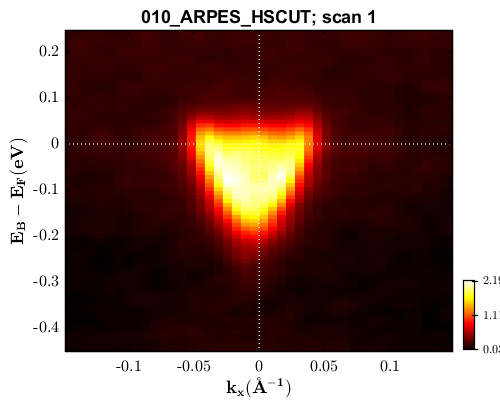

ans = struct with fields:
       FileName: '010_ARPES_HSCUT'
         H5file: '010_ARPES_HSCUT.h5'
           Type: "Eb(k)"
          index: 1
           meta: [1×1 struct]
       raw_data: [1376×391 double]
        raw_tht: [1×391 double]
         raw_eb: [1376×1 double]
            deb: 0.0450
             hv: 586
            dhv: 0.0750
           tltM: 2.8006
           thtM: 0
           Temp: 81.9000
      eb_shifts: {[0.8238]}
    eb_ref_file: '010_ARPES_HSCUT_EF'
             eb: [82×44 double]
            tht: [82×44 double]
           data: [82×44 double]
      surfNormX: 0.1924
             kx: [82×44 double]
             ky: 0.6060
             kz: 12.5700


xLims       = [-0.15, 0.15];    % x-axis limits to crop (if empty like [], does not crop this axis)
yLims       = [-0.45, 0.25];     % y-axis limits to crop (if empty like [], does not crop this axis)
zLims       = [];               % z-axis limits to crop (if empty like [], does not crop this axis)
for i = 1:length(arpes_dat)
    arpes_dat{i} = data_crop3D(arpes_dat{i}, xLims, yLims, zLims);
    view_data(arpes_dat{i}); arpes_dat{i}
end

**(B) Binding energy re-alignment to make sure EF is correct**

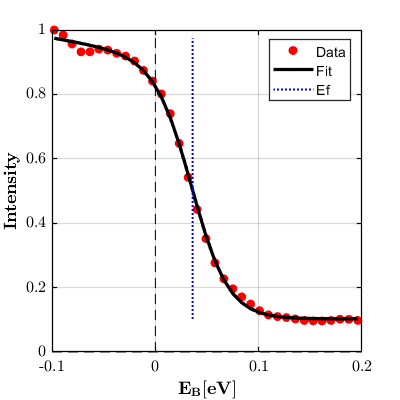

alignType   = "fit2ref-5%";         % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];                   % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.05;                 % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 0.15;                 % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];                   % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';               % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(arpes_dat)
    arpes_dat{i}  = align_energy(arpes_dat{i}, align_args); 
end

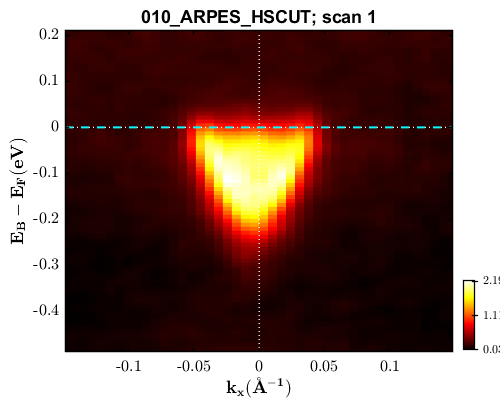

view_data(arpes_dat{1}); 
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(C) Extracting an MDC cut through the Fermi-edge**

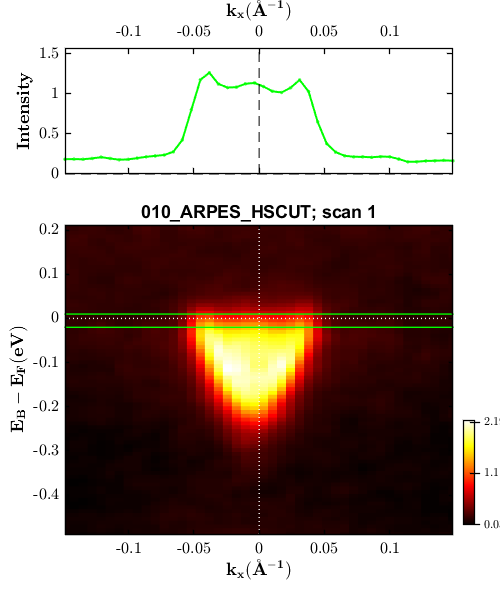

cutStr_01 = struct with fields:
    isocut_args: {[1]  ["MDC"]  [-0.1000 0]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "MDC"
         IsoVal: -0.0500
         IsoWin: 0.0500
         IsoNum: 1
           XCut: [1×335 double]
           DCut: [1×335 double]


nFrame          = 1;                    % Scan number to be cut
cutType         = "MDC";                % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = [-0.02, 0.01];          % Integration window of the cut to be made.
isocut_args     = {nFrame, cutType, cutWin};
[mdcStr, ~]     = extract_isoCut(arpes_dat{1}, isocut_args); cutStr_01

**(D) Extracting kF based on gradient method**

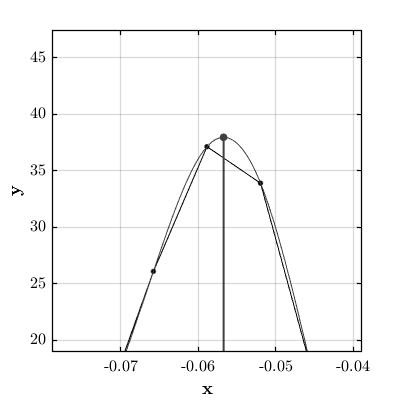

1) x = -0.06 eV, y = 37.96 


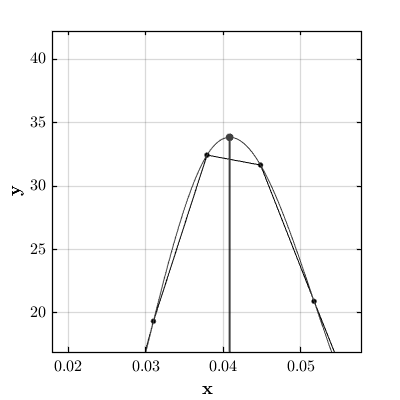

1) x = 0.04 eV, y = 33.84 


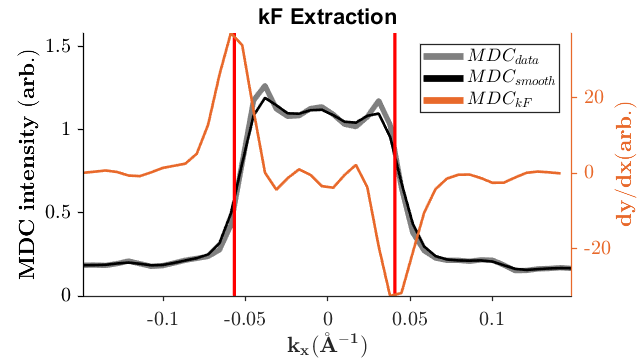

kfType          = "spline";
dkSmoothType    = "Gaco2";
dkSmoothVal     = 1.0;
kF_args         = {kfType, dkSmoothType, dkSmoothVal};
kfStr           = extract_kf(mdcStr.XCut, mdcStr.DCut, kF_args); 

kfStr

kfStr = struct with fields:
    kF_args: {["spline"]  ["Gaco2"]  [1]}
      XCut0: [1×44 double]
      DCut0: [1×44 double]
      XCut1: [1×44 double]
      DCut1: [1×44 double]
      XCut2: [1×43 double]
      DCut2: [43×1 double]
      kFlhs: -0.0567
      kFrhs: 0.0408
         KF: 0.0975


## Appendix IV - Extracting electron confinement from kz-broadened line profile

**(A) Create an artificial dataset that simulates a kz-broadened line-profile**

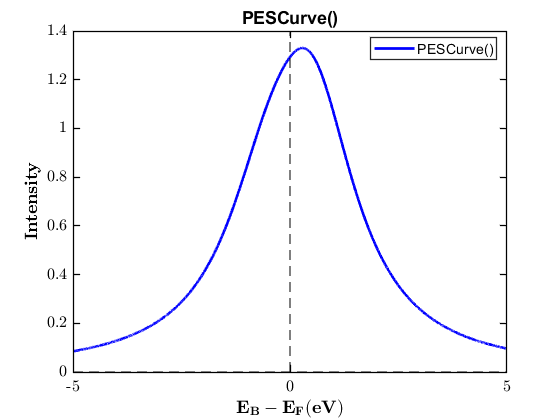

% 1 - Defining the input parameters
xdat = linspace(-5, 5, 1e4);
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "sGL", "pGL", "G", "L", "DS")
BE      =  0.5;     % scalar of the binding energy of PE curve.
INT     =  1.0;     % scalar of the peak intensity of PE curve.
FWHM    =  2.5;     % scalar of the FWHM of the PE curve.
MR      =  1.0;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSI     =  0.5;     % calar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.0;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
% 2 - Calculating the lineshape
zdat    = PESCurve(xdat, TYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY);
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); plot(xdat, zdat, 'b-', 'linewidth', 2);
gca_props(); title('PESCurve()', 'Interpreter','none'); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
legend({'PESCurve()'}, 'location', 'best', 'Interpreter','none');

**(B) Define the properties of the model to be fitted**

% 1 - Extracting the material parameters
mat_props           = get_mpd_props('Si');
% DEFINING THE TYPES OF CURVES TO BE USED
iparams = {};
cTYPE   = "sGLA";  % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")
% 1 - DEFINING THE INITIAL CONDITIONS OF THE XPS COMPONENTS
KZ0     =  0.5;      % scalar of the initial location of the principal kz curve.
INT     =  1.0;      % scalar of the peak intensity of the principal kz curve.
MFP     = eimfp_optical(380-mat_props.ELE_WFUNC, 'Si');    % scalar of the MFP contribution to the FWHM. [Ang]
DZ      = 0.9;      % scalar of the dz-confinement contribution to the FWHM. [Ang]
MR      =  1.0;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
SKZ0    = -1.0;     % scalar of the kz position of secondary kz curve.
SINT    =  0.5;     % scalar of the branching ratio of secondary kz curve.
ASY     =  0.0;     % scalar of the curve asymmetry parameter (usually for metallic systems).
BGR     =  0.0;     % scalar of the background to add
iparams{1} = [KZ0, INT, MFP, DZ, MR, SKZ0, SINT, ASY, BGR]; iparams{1}

ans =     0.5000    1.0000   11.7084    0.9000    1.0000   -1.0000    0.5000         0         0


% 2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
% -- Lower bounds
iparams{2} = iparams{1}; 
iparams{2}(:,1) = iparams{1}(:,1) - 0.05;
iparams{2}(:,2) = iparams{1}(:,2) - 0.50;
iparams{2}(:,3) = iparams{1}(:,3) - 0.05;
iparams{2}(:,4) = iparams{1}(:,4) - 2.0;
iparams{2}(:,5) = iparams{1}(:,5) - 0;
iparams{2}(:,6) = iparams{1}(:,6) - 0.05;
iparams{2}(:,7) = iparams{1}(:,7) - 0.50;
iparams{2}(:,8) = iparams{1}(:,8) - 0; 
iparams{2}(:,9) = iparams{1}(:,9) - 0.05; 
iparams{2}

ans =     0.4500    0.5000   11.6584   -1.1000    1.0000   -1.0500         0         0   -0.0500


% -- Upper bounds
iparams{3}      = iparams{1}; 
iparams{3}(:,1) = iparams{1}(:,1) + 0.05;
iparams{3}(:,2) = iparams{1}(:,2) + 0.50; 
iparams{3}(:,3) = iparams{1}(:,3) + 0.05; 
iparams{3}(:,4) = iparams{1}(:,4) + 2.0; 
iparams{3}(:,5) = iparams{1}(:,5) + 0.00; 
iparams{3}(:,6) = iparams{1}(:,6) + 0.05;
iparams{3}(:,7) = iparams{1}(:,7) + 0.50;
iparams{3}(:,8) = iparams{1}(:,8) + 0.50;
iparams{3}(:,9) = iparams{1}(:,9) + 0.05;
iparams{3}

ans =     0.5500    1.5000   11.7584    2.9000    1.0000   -0.9500    1.0000    0.5000    0.0500


**(C) Preview the initial conditions of the kz model**

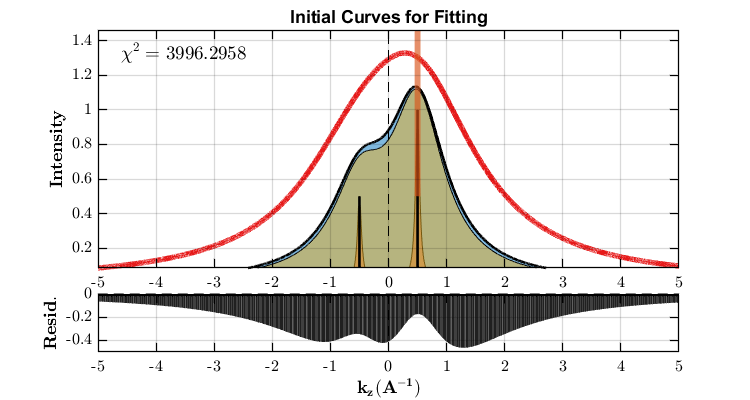

kz2model_view_init(xdat, zdat, cTYPE, iparams);

**(D) Running the solver to find the best fit**

solve_type  = "lsqcurvefit";
kz2model_fitdat  = kz2model_solver(xdat, zdat, cTYPE, iparams, solve_type); kz2model_fitdat


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


kz2model_fitdat = struct with fields:
    solve_type: "lsqcurvefit"
         cTYPE: "sGLA"
       iparams: {[0.5000 1 11.7084 0.9000 1 -1 0.5000 0 0]  [0.4500 0.5000 11.6584 -1.1000 1 -1.0500 0 0 -0.0500]  [0.5500 1.5000 11.7584 2.9000 1 -0.9500 1 0.5000 0.0500]}
          xdat: [1×10000 double]
          ydat: [10000×1 double]
             X: [1×10000 double]
             D: [10000×1 double]
             M: [10000×1 double]
            M0: [10000×1 double]
            M1: [10000×1 double]
             B: [10000×1 double]
            DB: [10000×1 double]
            MB: [10000×1 double]
             R: [10000×1 double]
         CHISQ: 4.0426e-14
        MINFUN: 4.0426e-14
           DoF: 8
            XX: [1000×1 double]
           YY0: [1000×1 double]
           YY1: [1000×1 double]
            YY: [1000×1 double]
        params: [9×1 double]
           KZ0: 0.5000
           INT: 1.0000
           MFP: 11.6940
            DZ: 0.4142
            MR: 1
          SKZ0: -1.0000
         

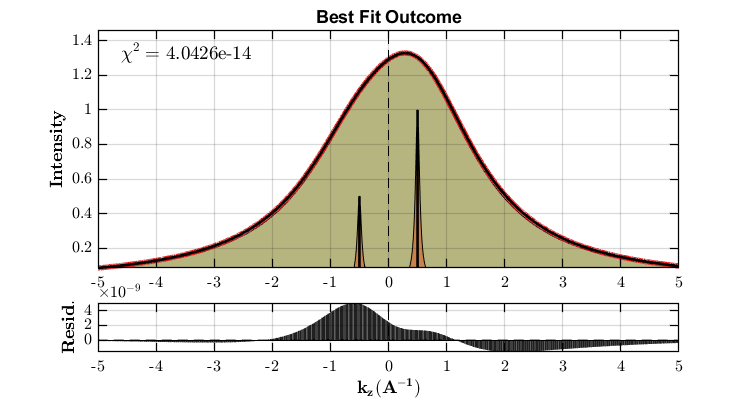

kz2model_view_fit(kz2model_fitdat);

**(E) Stating the electron confinement (in Angstroms) based on kz-broadening**

kz2model_fitdat.DZ

ans = 0.4142